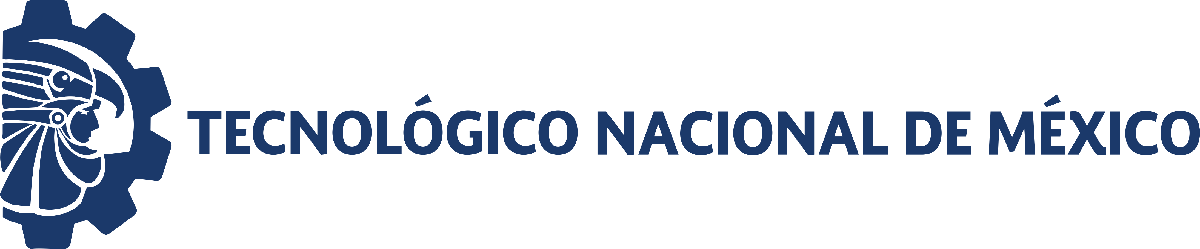                                 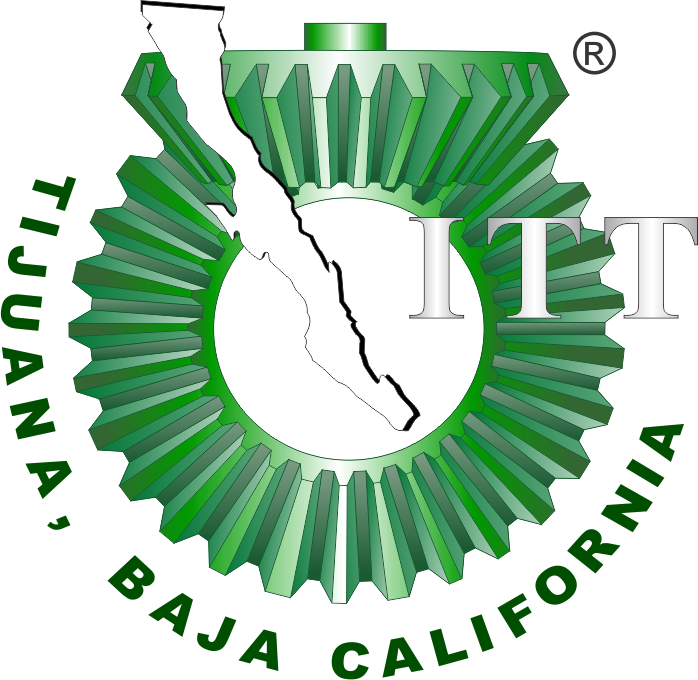

# Práctica cero: Mecánica pulmonar

**Departamento de Ingeniería Eléctrica y Electrónica, Ingeniería Biomédica**

**Tecnológico Nacional de México [TecNM - Tijuana], Blvd. Alberto Limón Padilla s/n, C.P. 22454, Tijuana, B.C., México**

## Información general

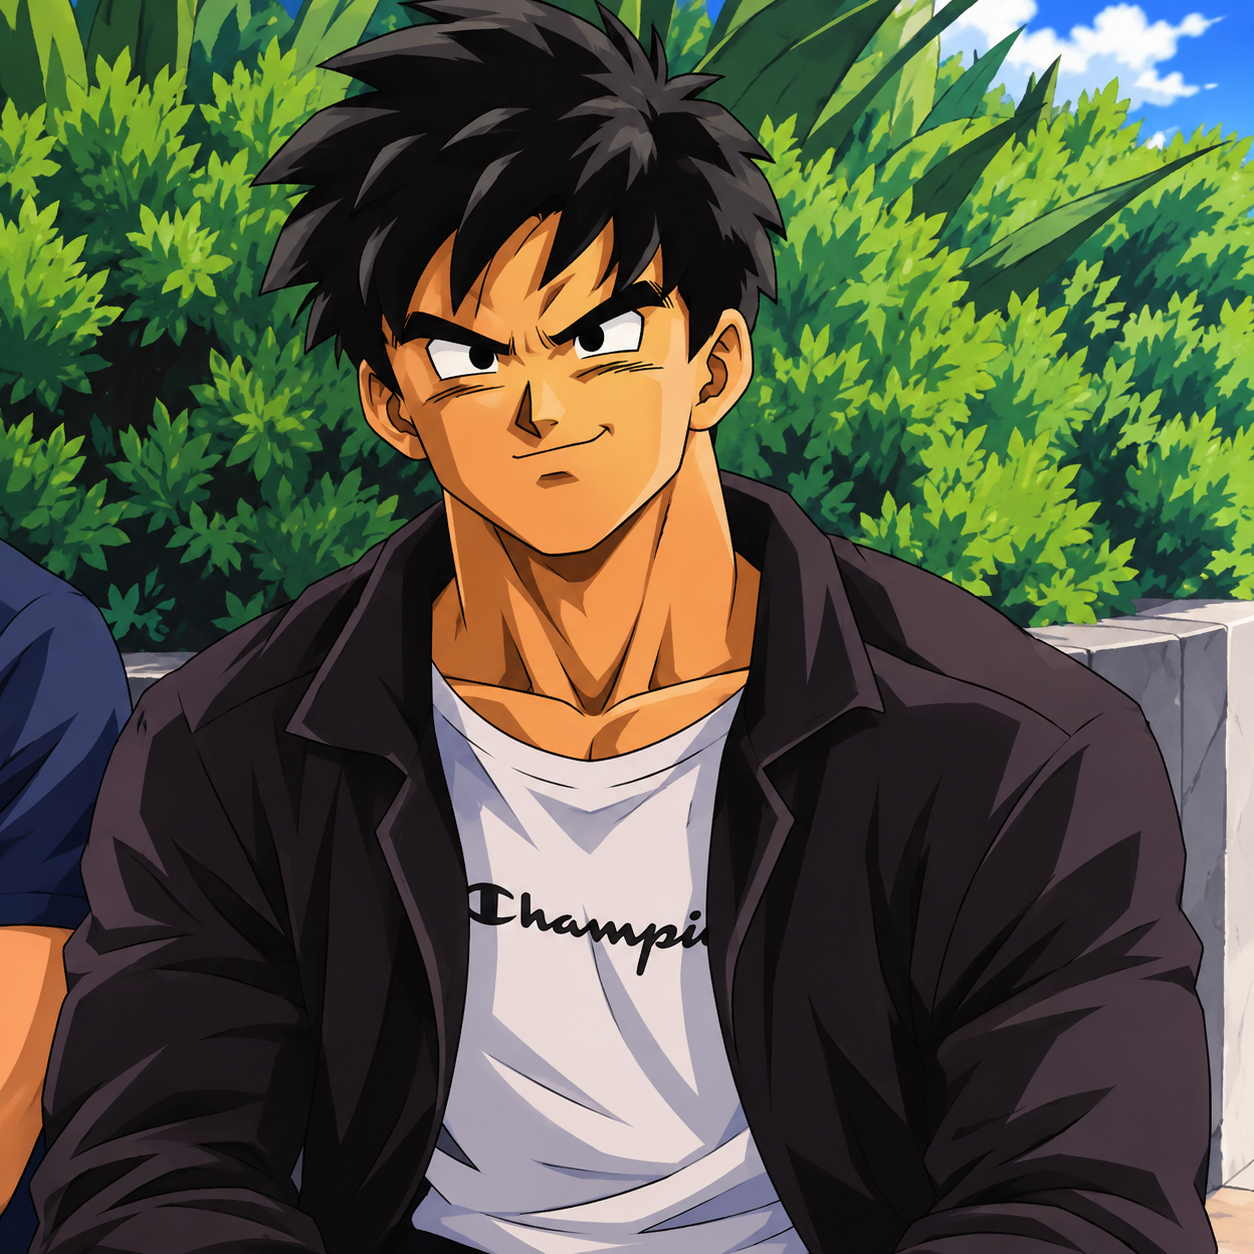

Nombre del alumno: Morales Diaz Ramon Ivan 

Número de control: 24210589

Correo institucional: l24210589**@tectijuana.edu.mx**

Asignatura: **Modelado de Sistemas Fisiológicos**

Docente: **Dr. Paul Antonio Valle Trujillo; paul.valle@tectijuana.edu.mx**

## Datos de la simulación

clc; clear; close all; warning('off','all')
open_system('sistema_2026')
parameters.StopTime = '10';
parameters.Solver = 'ode15s';
parameters.MaxStep = '1e-3';

## Respuesta al escalón

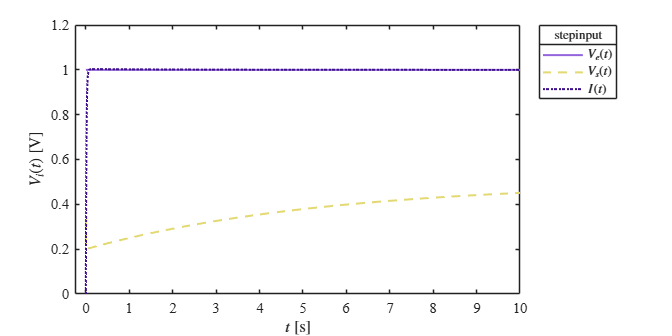

set_param('sistema_2026/S1','sw','1')
set_param('sistema_2026/Ve(t)','sw','1')
x1 = sim('sistema_2026',parameters);
plotsignals(x1.t,x1.Ve,x1.Vs,x1.PID,'step')

## Respuesta al impulso

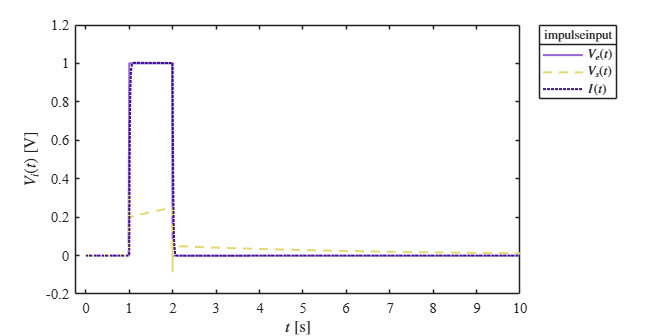

set_param('sistema_2026/S1','sw','0')
set_param('sistema_2026/Ve(t)','sw','1')
x2 = sim('sistema_2026',parameters);
plotsignals(x2.t,x2.Ve,x2.Vs,x2.PID,'impulse')

## Respuesta a la rampa

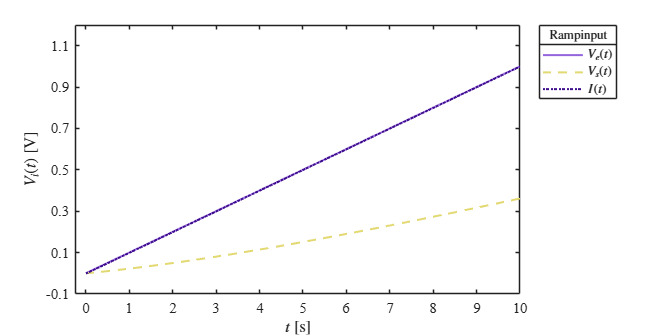

set_param('sistema_2026/S2','sw','1')
set_param('sistema_2026/Ve(t)','sw','0')
x3 = sim('sistema_2026',parameters);
plotsignals(x3.t,x3.Ve,x3.Vs,x3.PID,'Ramp')

## Respuesta a la función sinusoidal

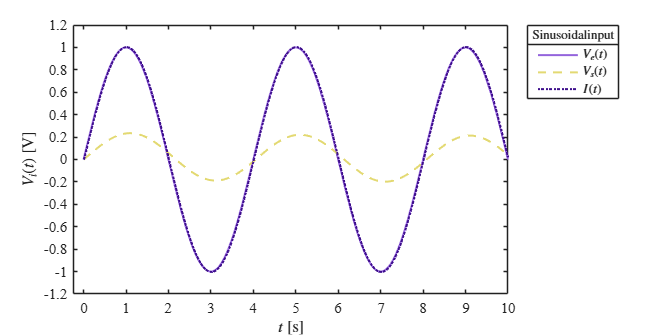

set_param('sistema_2026/S2','sw','0')
set_param('sistema_2026/Ve(t)','sw','0')
x4 = sim('sistema_2026',parameters);
plotsignals(x4.t,x4.Ve,x4.Vs,x4.PID,'Sinusoidal')

## Funcion: Respuestas de la simulacion

function plotsignals (t,Pao,PA,PID,signal)
    set(figure(),'color','w')
    set(gcf,'units','inches','position',[1,1,7,3.5])
    set(gca,'fontname','times new roman','fontsize',11)
    hold on; grid off; box on;
    clr1 = ([149, 100, 221])/256;
    clr2 = ([228, 218, 114])/256;
    clr3 = ([62, 15, 141])/256;
    order = [clr1;clr2;clr3]; colororder(order)
    
    plot(t,Pao,'-',t,PA,'--',t,PID,':','LineWidth',1.5)
    L = legend('$V_e(t)$','$V_s(t)$','$I(t)$');
    set(L,'interpreter','latex','location','northeastoutside','orientation','vertical')
    title(L,[signal,'input'])
    xlabel('$t$ [s]','Interpreter','latex')
    ylabel('$V_i(t)$ [V]','Interpreter','latex')
    xlim([-0.25 10]); xticks(0:1:10)
    
    if signal == "Step"
        ylim([0 1.2]); yticks(0:0.2:1.2)
    elseif signal == "Impulse"
        ylim([-0.2 1.2]); yticks(-0.2:0.2:1.2)
    elseif signal == "Ramp"
        ylim([-0.1 1.2]); yticks(-0.1:0.2:1.2)
    elseif signal == "Sinusoidal"
        ylim([-1.2 1.2]); yticks(-1.2:0.2:1.2)
        

    end
    exportgraphics(gcf,[signal,'_matlab.pdf'],'ContentType','vector')
     
end